# `Exp-05:Partial Derivatives,Jacobians,Polar Curves`

## `Table of Contents:`

- Partial Derivatives

- Jacobians

- Polar Curves

Partial Derivatives

syms x y
u=x^2-y^2

$$u = x^{2}-y^{2}$$

v=2*x*y

$$v = 2\,x\,y$$

u_x=diff(u,x)

$$u\_x = 2\,x$$

u_y=diff(u,y)

$$u\_y = -2\,y$$

v_x=diff(v,x)

$$v\_x = 2\,y$$

v_y=diff(v,y)

$$v\_y = 2\,x$$

Jacobians

J=[u_x u_y ; v_x v_y]

$$J = \left(\begin{array}{cc} 2\,x & -2\,y\\ 2\,y & 2\,x \end{array}\right)$$

J=det(J)

$$J = 4\,x^{2}+4\,y^{2}$$

J=simplify(J)

$$J = 4\,x^{2}+4\,y^{2}$$

syms x y 
u=x^2-y^2;
v=2*x*y;
J=jacobian([u,v],[x,y])

$$J = \left(\begin{array}{cc} 2\,x & -2\,y\\ 2\,y & 2\,x \end{array}\right)$$

J=det(J)

$$J = 4\,x^{2}+4\,y^{2}$$

J=simplify(J)

$$J = 4\,x^{2}+4\,y^{2}$$

Example-1

syms theta r
x=r*cos(theta);
y=r*sin(theta);
J1=jacobian([x,y],[r,theta])

$$J1 = \left(\begin{array}{cc} \cos\left(\theta \right) & -r\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & r\,\cos\left(\theta \right) \end{array}\right)$$

J1=simplify(det(J1))

$$J1 = r$$

Example-2

syms r s t
x=r*cos(s)*cos(t);
y=r*cos(s)*cos(t);
z=r*sin(s);
J2=jacobian([x,y,z],[r,s,t])

$$J2 = \left(\begin{array}{ccc} \cos\left(s\right)\,\cos\left(t\right) & -r\,\cos\left(t\right)\,\sin\left(s\right) & -r\,\cos\left(s\right)\,\sin\left(t\right)\\ \cos\left(s\right)\,\cos\left(t\right) & -r\,\cos\left(t\right)\,\sin\left(s\right) & -r\,\cos\left(s\right)\,\sin\left(t\right)\\ \sin\left(s\right) & r\,\cos\left(s\right) & 0 \end{array}\right)$$

J2=simplify(det(J2))

$$J2 = 0$$

Example-3

syms x y z u v w
u=x+3*y^2-z^3;
v=4*x^3*y*z;
w=2*z^2-x*y;
J3=jacobian([u,v,w],[x,y,z])

$$J3 = \left(\begin{array}{ccc} 1 & 6\,y & -3\,z^{2}\\ 12\,x^{2}\,y\,z & 4\,x^{3}\,z & 4\,x^{3}\,y\\ -y & -x & 4\,z \end{array}\right)$$

J3=simplify(det(J3))

$$J3 = 4\,x^{4}\,y-24\,x^{3}\,y^{3}+24\,x^{3}\,y\,z^{3}+16\,x^{3}\,z^{2}-288\,x^{2}\,y^{2}\,z^{2}$$

Polar Curves

clear
theta=linspace(0,2*pi,25)

theta =          0    0.2618    0.5236    0.7854    1.0472    1.3090    1.5708    1.8326    2.0944    2.3562    2.6180    2.8798    3.1416    3.4034    3.6652    3.9270    4.1888    4.4506    4.7124    4.9742    5.2360    5.4978    5.7596    6.0214    6.2832


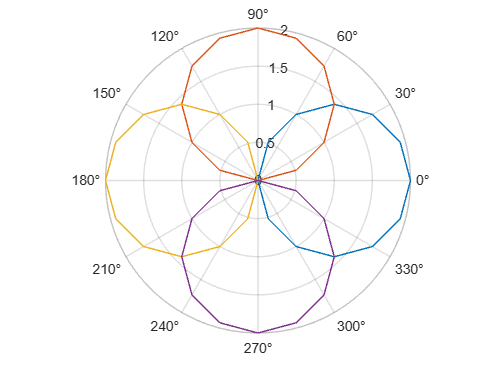

r1=2*cos(theta);
r2=2*sin(theta);
r3=-r1;
r4=-r2;
polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

Example-1

clear
theta=linspace(0,2*pi,25)

theta =          0    0.2618    0.5236    0.7854    1.0472    1.3090    1.5708    1.8326    2.0944    2.3562    2.6180    2.8798    3.1416    3.4034    3.6652    3.9270    4.1888    4.4506    4.7124    4.9742    5.2360    5.4978    5.7596    6.0214    6.2832


r1=2*(1+sin(theta))

r1 =     2.0000    2.5176    3.0000    3.4142    3.7321    3.9319    4.0000    3.9319    3.7321    3.4142    3.0000    2.5176    2.0000    1.4824    1.0000    0.5858    0.2679    0.0681         0    0.0681    0.2679    0.5858    1.0000    1.4824    2.0000


r2=-2*1+sin(theta)

r2 =    -2.0000   -1.7412   -1.5000   -1.2929   -1.1340   -1.0341   -1.0000   -1.0341   -1.1340   -1.2929   -1.5000   -1.7412   -2.0000   -2.2588   -2.5000   -2.7071   -2.8660   -2.9659   -3.0000   -2.9659   -2.8660   -2.7071   -2.5000   -2.2588   -2.0000


r3=1+sin(theta)

r3 =     1.0000    1.2588    1.5000    1.7071    1.8660    1.9659    2.0000    1.9659    1.8660    1.7071    1.5000    1.2588    1.0000    0.7412    0.5000    0.2929    0.1340    0.0341         0    0.0341    0.1340    0.2929    0.5000    0.7412    1.0000


r4=-(1+sin(theta))

r4 =    -1.0000   -1.2588   -1.5000   -1.7071   -1.8660   -1.9659   -2.0000   -1.9659   -1.8660   -1.7071   -1.5000   -1.2588   -1.0000   -0.7412   -0.5000   -0.2929   -0.1340   -0.0341         0   -0.0341   -0.1340   -0.2929   -0.5000   -0.7412   -1.0000


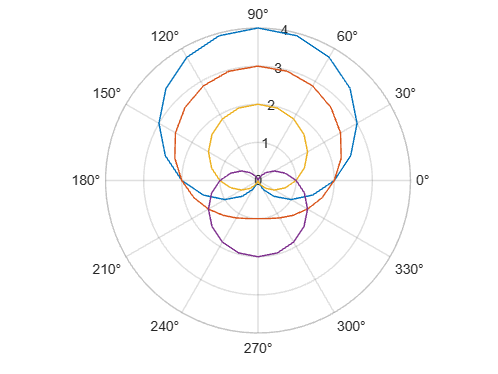

polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

Example-2

clear
theta=linspace(pi,3*pi)

theta =     3.1416    3.2051    3.2685    3.3320    3.3955    3.4589    3.5224    3.5859    3.6493    3.7128    3.7763    3.8397    3.9032    3.9667    4.0301    4.0936    4.1571    4.2205    4.2840    4.3475    4.4109    4.4744    4.5379    4.6013    4.6648    4.7283    4.7917    4.8552    4.9187    4.9821    5.0456    5.1091    5.1725    5.2360    5.2995    5.3629    5.4264    5.4899    5.5533    5.6168    5.6803    5.7437    5.8072    5.8707    5.9341    5.9976    6.0611    6.1245    6.1880    6.2515


r1=1-cos(theta)

r1 =     2.0000    1.9980    1.9920    1.9819    1.9679    1.9501    1.9284    1.9029    1.8738    1.8413    1.8053    1.7660    1.7237    1.6785    1.6306    1.5801    1.5272    1.4723    1.4154    1.3569    1.2969    1.2358    1.1736    1.1108    1.0476    0.9841    0.9208    0.8577    0.7952    0.7335    0.6729    0.6137    0.5559    0.5000    0.4461    0.3944    0.3451    0.2985    0.2547    0.2139    0.1763    0.1420    0.1112    0.0839    0.0603    0.0405    0.0246    0.0126    0.0045    0.0005


r2=2*1-cos(theta)

r2 =     3.0000    2.9980    2.9920    2.9819    2.9679    2.9501    2.9284    2.9029    2.8738    2.8413    2.8053    2.7660    2.7237    2.6785    2.6306    2.5801    2.5272    2.4723    2.4154    2.3569    2.2969    2.2358    2.1736    2.1108    2.0476    1.9841    1.9208    1.8577    1.7952    1.7335    1.6729    1.6137    1.5559    1.5000    1.4461    1.3944    1.3451    1.2985    1.2547    1.2139    1.1763    1.1420    1.1112    1.0839    1.0603    1.0405    1.0246    1.0126    1.0045    1.0005


r3=-(1-cos(theta))

r3 =    -2.0000   -1.9980   -1.9920   -1.9819   -1.9679   -1.9501   -1.9284   -1.9029   -1.8738   -1.8413   -1.8053   -1.7660   -1.7237   -1.6785   -1.6306   -1.5801   -1.5272   -1.4723   -1.4154   -1.3569   -1.2969   -1.2358   -1.1736   -1.1108   -1.0476   -0.9841   -0.9208   -0.8577   -0.7952   -0.7335   -0.6729   -0.6137   -0.5559   -0.5000   -0.4461   -0.3944   -0.3451   -0.2985   -0.2547   -0.2139   -0.1763   -0.1420   -0.1112   -0.0839   -0.0603   -0.0405   -0.0246   -0.0126   -0.0045   -0.0005


r4=-2*(1-cos(theta))

r4 =    -4.0000   -3.9960   -3.9839   -3.9639   -3.9359   -3.9001   -3.8567   -3.8059   -3.7477   -3.6825   -3.6105   -3.5321   -3.4475   -3.3570   -3.2611   -3.1601   -3.0545   -2.9445   -2.8308   -2.7138   -2.5938   -2.4715   -2.3473   -2.2217   -2.0952   -1.9683   -1.8415   -1.7154   -1.5904   -1.4671   -1.3459   -1.2273   -1.1119   -1.0000   -0.8922   -0.7888   -0.6903   -0.5971   -0.5095   -0.4279   -0.3526   -0.2840   -0.2223   -0.1678   -0.1206   -0.0810   -0.0491   -0.0251   -0.0091   -0.0010


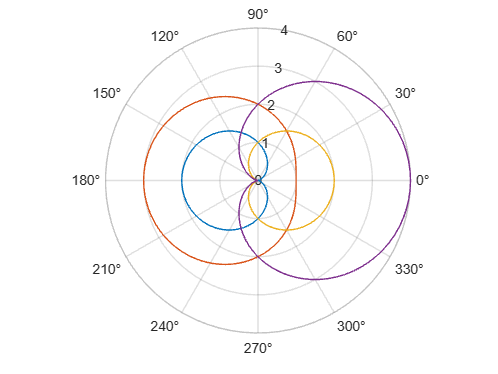

polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

Example-3

clear
theta=linspace(pi/2,3*pi/2)

theta =     1.5708    1.6025    1.6343    1.6660    1.6977    1.7295    1.7612    1.7929    1.8247    1.8564    1.8881    1.9199    1.9516    1.9833    2.0151    2.0468    2.0785    2.1103    2.1420    2.1737    2.2055    2.2372    2.2689    2.3007    2.3324    2.3641    2.3959    2.4276    2.4593    2.4911    2.5228    2.5545    2.5863    2.6180    2.6497    2.6815    2.7132    2.7449    2.7767    2.8084    2.8401    2.8719    2.9036    2.9353    2.9671    2.9988    3.0305    3.0623    3.0940    3.1257


r9=2*(1+sin(theta));
theta=linspace(pi/2,3*pi/2)

theta =     1.5708    1.6025    1.6343    1.6660    1.6977    1.7295    1.7612    1.7929    1.8247    1.8564    1.8881    1.9199    1.9516    1.9833    2.0151    2.0468    2.0785    2.1103    2.1420    2.1737    2.2055    2.2372    2.2689    2.3007    2.3324    2.3641    2.3959    2.4276    2.4593    2.4911    2.5228    2.5545    2.5863    2.6180    2.6497    2.6815    2.7132    2.7449    2.7767    2.8084    2.8401    2.8719    2.9036    2.9353    2.9671    2.9988    3.0305    3.0623    3.0940    3.1257


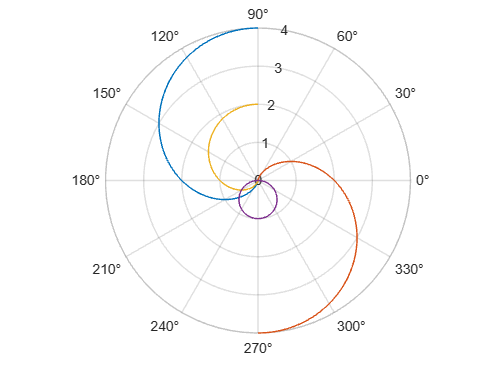

r10=-2*(1+sin(theta));
r11=1+sin(theta);
r12=-sin(theta);
polarplot(theta,r9)
hold on
polarplot(theta,r10)
polarplot(theta,r11)
polarplot(theta,r12)
hold off

Example-4

clear
theta=linspace(pi/2,3*pi/2)

theta =     1.5708    1.6025    1.6343    1.6660    1.6977    1.7295    1.7612    1.7929    1.8247    1.8564    1.8881    1.9199    1.9516    1.9833    2.0151    2.0468    2.0785    2.1103    2.1420    2.1737    2.2055    2.2372    2.2689    2.3007    2.3324    2.3641    2.3959    2.4276    2.4593    2.4911    2.5228    2.5545    2.5863    2.6180    2.6497    2.6815    2.7132    2.7449    2.7767    2.8084    2.8401    2.8719    2.9036    2.9353    2.9671    2.9988    3.0305    3.0623    3.0940    3.1257


r1=1-cos(theta)

r1 =     1.0000    1.0317    1.0634    1.0951    1.1266    1.1580    1.1893    1.2203    1.2511    1.2817    1.3120    1.3420    1.3717    1.4009    1.4298    1.4582    1.4862    1.5137    1.5406    1.5671    1.5929    1.6182    1.6428    1.6668    1.6901    1.7127    1.7346    1.7557    1.7761    1.7958    1.8146    1.8326    1.8497    1.8660    1.8815    1.8960    1.9096    1.9224    1.9341    1.9450    1.9549    1.9638    1.9718    1.9788    1.9848    1.9898    1.9938    1.9969    1.9989    1.9999


r2=2*1-cos(theta)

r2 =     2.0000    2.0317    2.0634    2.0951    2.1266    2.1580    2.1893    2.2203    2.2511    2.2817    2.3120    2.3420    2.3717    2.4009    2.4298    2.4582    2.4862    2.5137    2.5406    2.5671    2.5929    2.6182    2.6428    2.6668    2.6901    2.7127    2.7346    2.7557    2.7761    2.7958    2.8146    2.8326    2.8497    2.8660    2.8815    2.8960    2.9096    2.9224    2.9341    2.9450    2.9549    2.9638    2.9718    2.9788    2.9848    2.9898    2.9938    2.9969    2.9989    2.9999


r3=-(1-cos(theta))

r3 =    -1.0000   -1.0317   -1.0634   -1.0951   -1.1266   -1.1580   -1.1893   -1.2203   -1.2511   -1.2817   -1.3120   -1.3420   -1.3717   -1.4009   -1.4298   -1.4582   -1.4862   -1.5137   -1.5406   -1.5671   -1.5929   -1.6182   -1.6428   -1.6668   -1.6901   -1.7127   -1.7346   -1.7557   -1.7761   -1.7958   -1.8146   -1.8326   -1.8497   -1.8660   -1.8815   -1.8960   -1.9096   -1.9224   -1.9341   -1.9450   -1.9549   -1.9638   -1.9718   -1.9788   -1.9848   -1.9898   -1.9938   -1.9969   -1.9989   -1.9999


r4=-2*(1-cos(theta))

r4 =    -2.0000   -2.0635   -2.1268   -2.1901   -2.2532   -2.3160   -2.3785   -2.4406   -2.5023   -2.5635   -2.6241   -2.6840   -2.7433   -2.8019   -2.8596   -2.9165   -2.9724   -3.0274   -3.0813   -3.1341   -3.1858   -3.2363   -3.2856   -3.3335   -3.3802   -3.4254   -3.4692   -3.5115   -3.5523   -3.5915   -3.6292   -3.6651   -3.6995   -3.7321   -3.7629   -3.7920   -3.8193   -3.8447   -3.8683   -3.8900   -3.9098   -3.9277   -3.9436   -3.9576   -3.9696   -3.9796   -3.9877   -3.9937   -3.9977   -3.9997


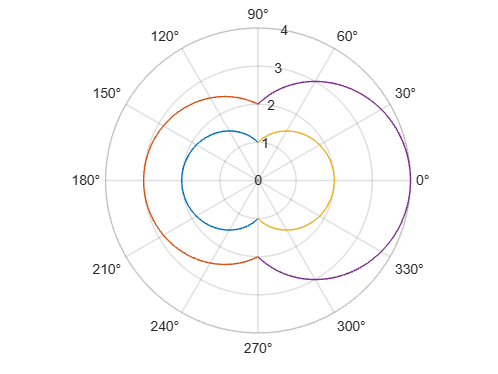

polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

Example-5

clear
theta=linspace(pi/2,3*pi/2)

theta =     1.5708    1.6025    1.6343    1.6660    1.6977    1.7295    1.7612    1.7929    1.8247    1.8564    1.8881    1.9199    1.9516    1.9833    2.0151    2.0468    2.0785    2.1103    2.1420    2.1737    2.2055    2.2372    2.2689    2.3007    2.3324    2.3641    2.3959    2.4276    2.4593    2.4911    2.5228    2.5545    2.5863    2.6180    2.6497    2.6815    2.7132    2.7449    2.7767    2.8084    2.8401    2.8719    2.9036    2.9353    2.9671    2.9988    3.0305    3.0623    3.0940    3.1257


r1=2*(1+sin(theta))

r1 =     4.0000    3.9990    3.9960    3.9909    3.9839    3.9749    3.9639    3.9509    3.9359    3.9190    3.9001    3.8794    3.8567    3.8322    3.8059    3.7777    3.7477    3.7160    3.6825    3.6474    3.6105    3.5721    3.5321    3.4905    3.4475    3.4029    3.3570    3.3097    3.2611    3.2112    3.1601    3.1078    3.0545    3.0000    2.9445    2.8881    2.8308    2.7727    2.7138    2.6541    2.5938    2.5329    2.4715    2.4096    2.3473    2.2846    2.2217    2.1585    2.0952    2.0317


r2=-2*1+sin(theta)

r2 =    -1.0000   -1.0005   -1.0020   -1.0045   -1.0080   -1.0126   -1.0181   -1.0246   -1.0321   -1.0405   -1.0499   -1.0603   -1.0716   -1.0839   -1.0971   -1.1112   -1.1262   -1.1420   -1.1587   -1.1763   -1.1947   -1.2139   -1.2340   -1.2547   -1.2763   -1.2985   -1.3215   -1.3451   -1.3694   -1.3944   -1.4199   -1.4461   -1.4728   -1.5000   -1.5277   -1.5559   -1.5846   -1.6137   -1.6431   -1.6729   -1.7031   -1.7335   -1.7642   -1.7952   -1.8264   -1.8577   -1.8892   -1.9208   -1.9524   -1.9841


r3=1+sin(theta)

r3 =     2.0000    1.9995    1.9980    1.9955    1.9920    1.9874    1.9819    1.9754    1.9679    1.9595    1.9501    1.9397    1.9284    1.9161    1.9029    1.8888    1.8738    1.8580    1.8413    1.8237    1.8053    1.7861    1.7660    1.7453    1.7237    1.7015    1.6785    1.6549    1.6306    1.6056    1.5801    1.5539    1.5272    1.5000    1.4723    1.4441    1.4154    1.3863    1.3569    1.3271    1.2969    1.2665    1.2358    1.2048    1.1736    1.1423    1.1108    1.0792    1.0476    1.0159


r4=-(1+sin(theta))

r4 =    -2.0000   -1.9995   -1.9980   -1.9955   -1.9920   -1.9874   -1.9819   -1.9754   -1.9679   -1.9595   -1.9501   -1.9397   -1.9284   -1.9161   -1.9029   -1.8888   -1.8738   -1.8580   -1.8413   -1.8237   -1.8053   -1.7861   -1.7660   -1.7453   -1.7237   -1.7015   -1.6785   -1.6549   -1.6306   -1.6056   -1.5801   -1.5539   -1.5272   -1.5000   -1.4723   -1.4441   -1.4154   -1.3863   -1.3569   -1.3271   -1.2969   -1.2665   -1.2358   -1.2048   -1.1736   -1.1423   -1.1108   -1.0792   -1.0476   -1.0159


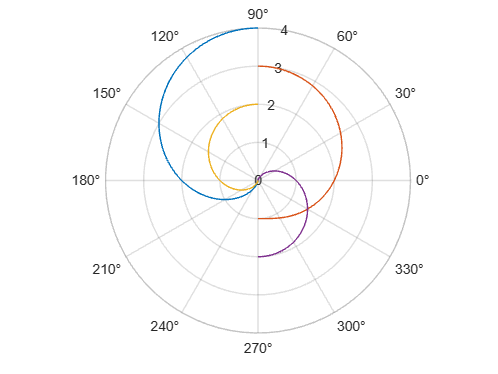

polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

Example-6

clear
theta=linspace(pi/2,3*pi/2)

theta =     1.5708    1.6025    1.6343    1.6660    1.6977    1.7295    1.7612    1.7929    1.8247    1.8564    1.8881    1.9199    1.9516    1.9833    2.0151    2.0468    2.0785    2.1103    2.1420    2.1737    2.2055    2.2372    2.2689    2.3007    2.3324    2.3641    2.3959    2.4276    2.4593    2.4911    2.5228    2.5545    2.5863    2.6180    2.6497    2.6815    2.7132    2.7449    2.7767    2.8084    2.8401    2.8719    2.9036    2.9353    2.9671    2.9988    3.0305    3.0623    3.0940    3.1257


r1=2*cos(theta)

r1 =     0.0000   -0.0635   -0.1268   -0.1901   -0.2532   -0.3160   -0.3785   -0.4406   -0.5023   -0.5635   -0.6241   -0.6840   -0.7433   -0.8019   -0.8596   -0.9165   -0.9724   -1.0274   -1.0813   -1.1341   -1.1858   -1.2363   -1.2856   -1.3335   -1.3802   -1.4254   -1.4692   -1.5115   -1.5523   -1.5915   -1.6292   -1.6651   -1.6995   -1.7321   -1.7629   -1.7920   -1.8193   -1.8447   -1.8683   -1.8900   -1.9098   -1.9277   -1.9436   -1.9576   -1.9696   -1.9796   -1.9877   -1.9937   -1.9977   -1.9997


r2=2*sin(theta)

r2 =     2.0000    1.9990    1.9960    1.9909    1.9839    1.9749    1.9639    1.9509    1.9359    1.9190    1.9001    1.8794    1.8567    1.8322    1.8059    1.7777    1.7477    1.7160    1.6825    1.6474    1.6105    1.5721    1.5321    1.4905    1.4475    1.4029    1.3570    1.3097    1.2611    1.2112    1.1601    1.1078    1.0545    1.0000    0.9445    0.8881    0.8308    0.7727    0.7138    0.6541    0.5938    0.5329    0.4715    0.4096    0.3473    0.2846    0.2217    0.1585    0.0952    0.0317


r3=-r1

r3 =    -0.0000    0.0635    0.1268    0.1901    0.2532    0.3160    0.3785    0.4406    0.5023    0.5635    0.6241    0.6840    0.7433    0.8019    0.8596    0.9165    0.9724    1.0274    1.0813    1.1341    1.1858    1.2363    1.2856    1.3335    1.3802    1.4254    1.4692    1.5115    1.5523    1.5915    1.6292    1.6651    1.6995    1.7321    1.7629    1.7920    1.8193    1.8447    1.8683    1.8900    1.9098    1.9277    1.9436    1.9576    1.9696    1.9796    1.9877    1.9937    1.9977    1.9997


r4=-r2

r4 =    -2.0000   -1.9990   -1.9960   -1.9909   -1.9839   -1.9749   -1.9639   -1.9509   -1.9359   -1.9190   -1.9001   -1.8794   -1.8567   -1.8322   -1.8059   -1.7777   -1.7477   -1.7160   -1.6825   -1.6474   -1.6105   -1.5721   -1.5321   -1.4905   -1.4475   -1.4029   -1.3570   -1.3097   -1.2611   -1.2112   -1.1601   -1.1078   -1.0545   -1.0000   -0.9445   -0.8881   -0.8308   -0.7727   -0.7138   -0.6541   -0.5938   -0.5329   -0.4715   -0.4096   -0.3473   -0.2846   -0.2217   -0.1585   -0.0952   -0.0317


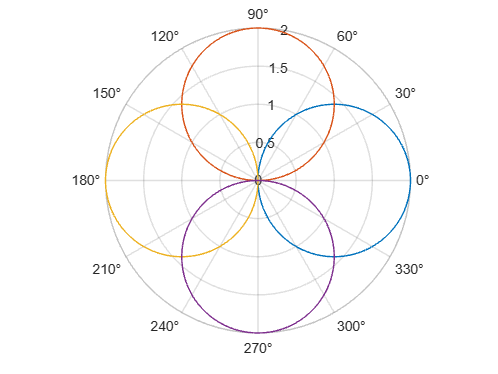

polarplot(theta,r1)
hold on
polarplot(theta,r2)
polarplot(theta,r3)
polarplot(theta,r4)
hold off

Diiferential Equations

Example-1

clear
t=linspace(0,2*pi,100);
r1=cos(t)

r1 =     1.0000    0.9980    0.9920    0.9819    0.9679    0.9501    0.9284    0.9029    0.8738    0.8413    0.8053    0.7660    0.7237    0.6785    0.6306    0.5801    0.5272    0.4723    0.4154    0.3569    0.2969    0.2358    0.1736    0.1108    0.0476   -0.0159   -0.0792   -0.1423   -0.2048   -0.2665   -0.3271   -0.3863   -0.4441   -0.5000   -0.5539   -0.6056   -0.6549   -0.7015   -0.7453   -0.7861   -0.8237   -0.8580   -0.8888   -0.9161   -0.9397   -0.9595   -0.9754   -0.9874   -0.9955   -0.9995


r2=-cos(t)

r2 =    -1.0000   -0.9980   -0.9920   -0.9819   -0.9679   -0.9501   -0.9284   -0.9029   -0.8738   -0.8413   -0.8053   -0.7660   -0.7237   -0.6785   -0.6306   -0.5801   -0.5272   -0.4723   -0.4154   -0.3569   -0.2969   -0.2358   -0.1736   -0.1108   -0.0476    0.0159    0.0792    0.1423    0.2048    0.2665    0.3271    0.3863    0.4441    0.5000    0.5539    0.6056    0.6549    0.7015    0.7453    0.7861    0.8237    0.8580    0.8888    0.9161    0.9397    0.9595    0.9754    0.9874    0.9955    0.9995


r3=t

r3 =          0    0.0635    0.1269    0.1904    0.2539    0.3173    0.3808    0.4443    0.5077    0.5712    0.6347    0.6981    0.7616    0.8251    0.8885    0.9520    1.0155    1.0789    1.1424    1.2059    1.2693    1.3328    1.3963    1.4597    1.5232    1.5867    1.6501    1.7136    1.7771    1.8405    1.9040    1.9675    2.0309    2.0944    2.1579    2.2213    2.2848    2.3483    2.4117    2.4752    2.5387    2.6021    2.6656    2.7291    2.7925    2.8560    2.9195    2.9829    3.0464    3.1099


r4=-t

r4 =          0   -0.0635   -0.1269   -0.1904   -0.2539   -0.3173   -0.3808   -0.4443   -0.5077   -0.5712   -0.6347   -0.6981   -0.7616   -0.8251   -0.8885   -0.9520   -1.0155   -1.0789   -1.1424   -1.2059   -1.2693   -1.3328   -1.3963   -1.4597   -1.5232   -1.5867   -1.6501   -1.7136   -1.7771   -1.8405   -1.9040   -1.9675   -2.0309   -2.0944   -2.1579   -2.2213   -2.2848   -2.3483   -2.4117   -2.4752   -2.5387   -2.6021   -2.6656   -2.7291   -2.7925   -2.8560   -2.9195   -2.9829   -3.0464   -3.1099


%Syntax: subplot(#rows,#columns,position)
subplot(2,2,1)
polarplot(t,r1)
title("Graph of cos(t)")

Example-2

subplot(2,2,2)
polarplot(t,r2)
title("Graph of -cos(t)")

Example-3

subplot(2,2,3)
polarplot(t,r3)
title("Graph of (t)")

Example-3

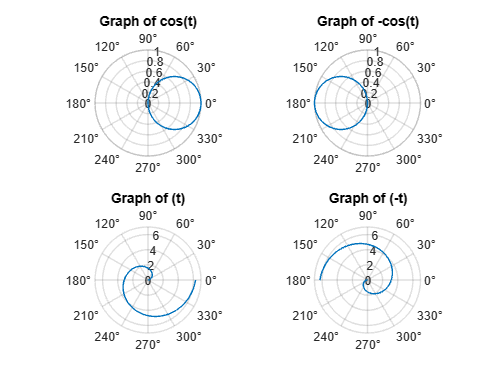

subplot(2,2,4)
polarplot(t,r4)
title("Graph of (-t)")